clc 
clear
% 1. Import Audio File 
    [Y,Fs] = audioread('testaudio.ogg');

% 2. Find FFT of audio file
    y = fft(Y);
    N = Fs;
    P2 = abs(y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1)
    f = Fs*(0:(N/2))/ N;

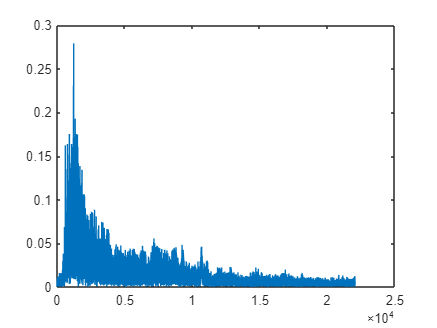

    plot(f, P1)

    

audioinfo('testaudio.ogg')

ans = struct with fields:
             Filename: 'C:\Jibin\Discrete Time Signals\Final Exam\Examples\testaudio.ogg'
    CompressionMethod: 'Vorbis'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 723938
             Duration: 16.4158
                Title: []
              Comment: []
               Artist: []








% 3. Determine Filter needed (Need to change around values)
%       May need multiple filters (Cascade) but make sure to find fft for each
%       process



%filtred my signal some how...

% 4. Play Audio 
player = audioplayer(Y,Fs);
play(player);